clear;
[f, Fs] = audioread('sample.wav');
T = 1/Fs;
L = length(f);
t = (0:L-1)*T;

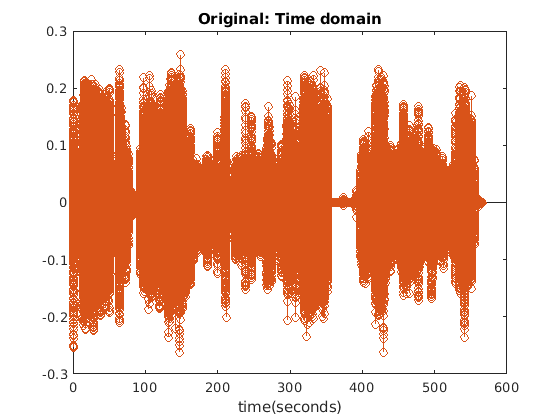

N = size(f, 1);
figure; stem(t,f);
title('Original: Time domain')
xlabel('time(seconds)')

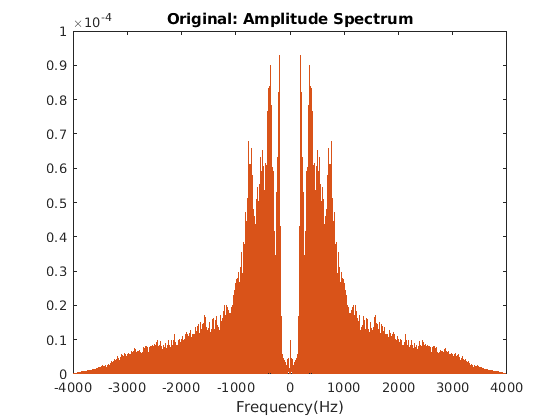

df = Fs/N;
w = (-(N/2):(N/2)-1) * df;
y = fft(f) / N; % For normalizing
y2 = fftshift(y);
figure;  plot(w, abs(y2))
title('Original: Amplitude Spectrum')
xlabel('Frequency(Hz)')

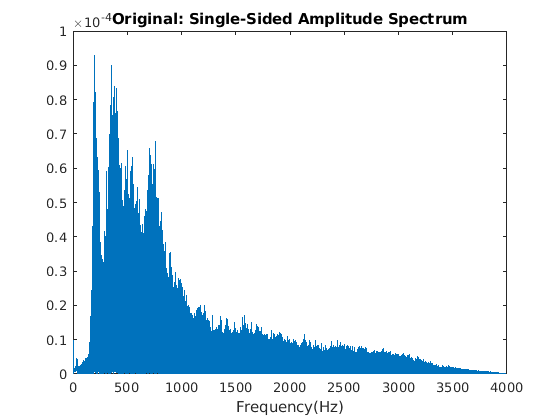

figure;
plot(Fs * (0:(L/2))/L, abs(y2(N/2:N)))
title('Original: Single-Sided Amplitude Spectrum')
xlabel('Frequency(Hz)')

[fmax1, f1index] = max(abs(y2(N/2:N)));
fmax1, f1index = f1index * df

fmax1 = 9.2937e-05

f1index = 196.6369

n = 2;
beginFreq = 190 / (Fs/2);
endFreq = 200 / (Fs/2);
[b, a] = butter(n, [beginFreq, endFreq], 'stop');
fOut = filter(b, a, f);

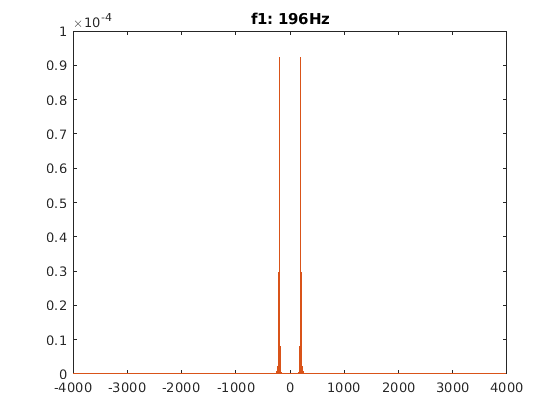

[b,a] = butter(n, [beginFreq, endFreq], 'bandpass');
f1 = filter(b, a, f);
figure;  plot(w, abs(fftshift(fft(f1)/N)));
title('f1: 196Hz')

[fmax2, f2index] = max(abs(fftshift(fft(fOut)/N)));
fmax2, f2index = Fs/2 - f2index * df

fmax2 =    1.0e-04 *

    0.8987    0.8987


f2index =   358.2744  358.2744


n = 2;
beginFreq = 355 / (Fs/2);
endFreq = 365 / (Fs/2);
[b,a] = butter(n, [beginFreq, endFreq], 'stop');
fOut = filter(b, a, fOut);

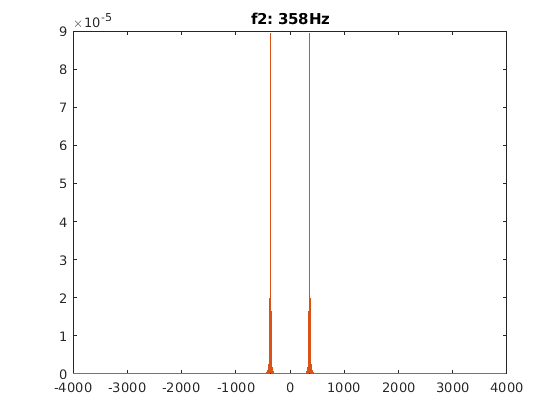

[b,a] = butter(n, [beginFreq, endFreq], 'bandpass');
f2 = filter(b, a, f);
figure;  plot(w,abs(fftshift(fft(f2)/N)));
title('f2: 358Hz');

snr(f,f1 + f2)

ans = 12.3470

Ym = max(max(max(fOut)),max(abs(min(fOut))));
fOut = fOut ./ Ym;

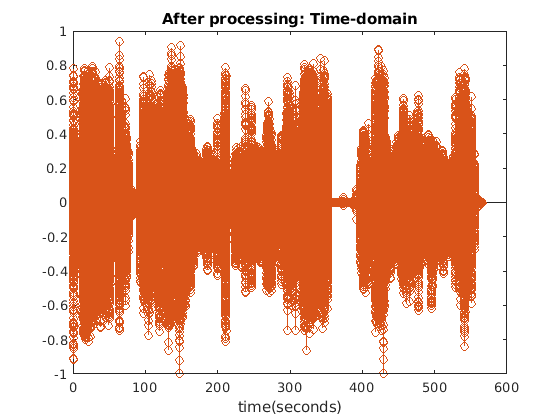

figure;  stem(t, fOut);
title('After processing: Time-domain');
xlabel('time(seconds)');

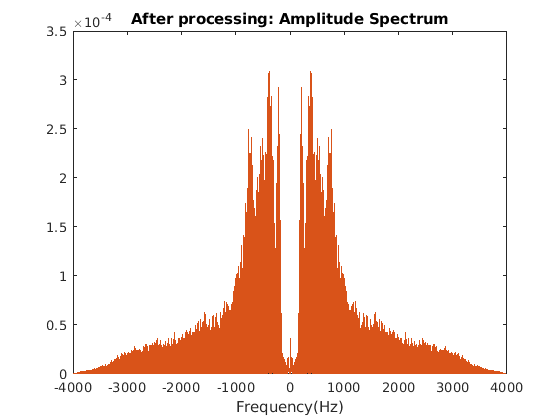


figure;  plot(w, abs(fftshift(fft(fOut)/N)));
title('After processing: Amplitude Spectrum');
xlabel('Frequency(Hz)');

pOrig = audioplayer(f,Fs); 
% pOrig.play;
p = audioplayer(fOut, Fs);  
% p.play;
pf1 = audioplayer(f1, Fs);  
% pf1.play;
pf2 = audioplayer(f2, Fs);  
% pf2.play;
audiowrite('handel_J_processed.wav', fOut, Fs);